### NeighbourhoodDiameter

- Wykresy poprawy

- Histogramy

- Tabela zestawieniowa

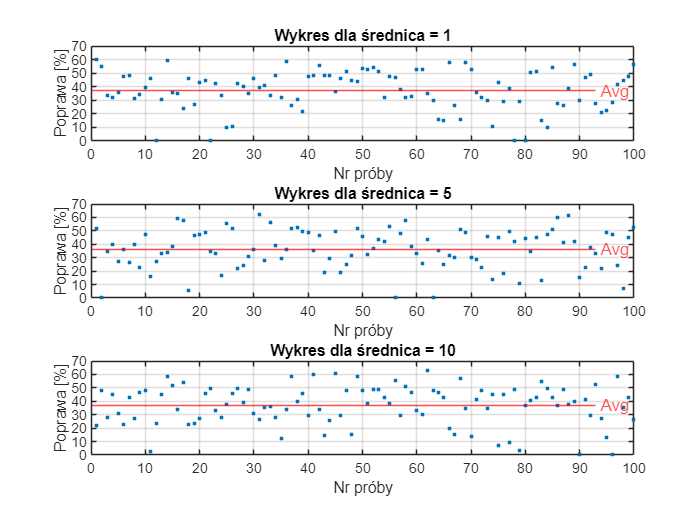

clear all; %#ok<CLALL>
load("results.mat")

neig_dia_1_rel_imp = neighbourhoodDiameterData(neighbourhoodDiameterData.ExperimentName == 1, {'RelativeImprovement'});
neig_dia_5_rel_imp = neighbourhoodDiameterData(neighbourhoodDiameterData.ExperimentName == 5, {'RelativeImprovement'});
neig_dia_10_rel_imp = neighbourhoodDiameterData(neighbourhoodDiameterData.ExperimentName ==10, {'RelativeImprovement'});

neig_dia_1_rel_imp.RelativeImprovement = neig_dia_1_rel_imp.RelativeImprovement * 100;
neig_dia_5_rel_imp.RelativeImprovement = neig_dia_5_rel_imp.RelativeImprovement * 100;
neig_dia_10_rel_imp.RelativeImprovement = neig_dia_10_rel_imp.RelativeImprovement * 100;


neig_dia_1_rel_imp_avg = mean(neig_dia_1_rel_imp.RelativeImprovement);
neig_dia_5_rel_imp_avg = mean(neig_dia_5_rel_imp.RelativeImprovement);
neig_dia_10_rel_imp_avg = mean(neig_dia_10_rel_imp.RelativeImprovement);

neig_dia_1_rel_imp_std = std(neig_dia_1_rel_imp.RelativeImprovement);
neig_dia_5_rel_imp_std = std(neig_dia_5_rel_imp.RelativeImprovement);
neig_dia_10_rel_imp_std = std(neig_dia_10_rel_imp.RelativeImprovement);

neig_dia_names = [1; 5; 10;];
neig_dia_avgs = [neig_dia_1_rel_imp_avg; neig_dia_5_rel_imp_avg; neig_dia_10_rel_imp_avg];
neig_dia_stds = [neig_dia_1_rel_imp_std; neig_dia_5_rel_imp_std; neig_dia_10_rel_imp_std];

neig_dia_comparison = table(neig_dia_names, neig_dia_avgs, neig_dia_stds, 'VariableNames', {'diameter', 'avg', 'std'});

max_value = max([max(neig_dia_1_rel_imp.RelativeImprovement), ...
                 max(neig_dia_5_rel_imp.RelativeImprovement), ...
                 max(neig_dia_10_rel_imp.RelativeImprovement)]);
y_axis_limit_plot = ceil(max_value / 10) * 10;

bin_width = 5;
max_count_100 = max(histcounts(neig_dia_1_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_1000 = max(histcounts(neig_dia_5_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_2000 = max(histcounts(neig_dia_10_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
y_axis_limit_hist = max([max_count_100, max_count_1000, max_count_2000]) + 10;

figure;

subplot(3, 1, 1);
plot(neig_dia_1_rel_imp.RelativeImprovement, '.');
yline(neig_dia_1_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla średnica = 1');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 2);
plot(neig_dia_5_rel_imp.RelativeImprovement, '.');
yline(neig_dia_5_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla średnica = 5');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 3);
plot(neig_dia_10_rel_imp.RelativeImprovement, '.');
yline(neig_dia_10_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla średnica = 10');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

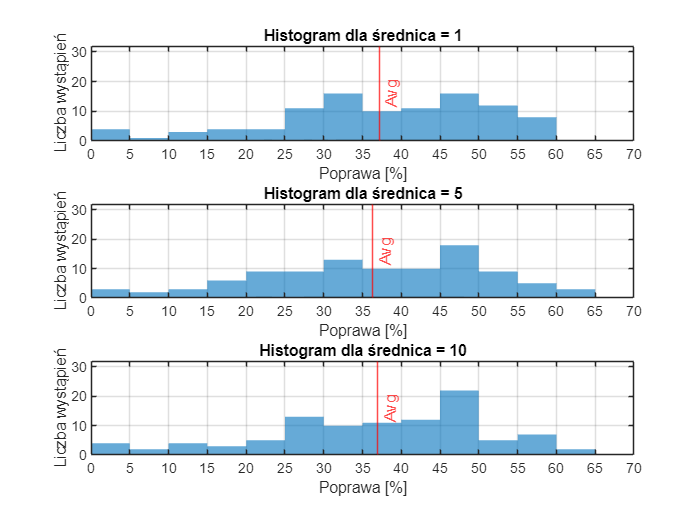


figure;

% Histogram dla neig_dia_1_rel_imp
subplot(3, 1, 1);
histogram(neig_dia_1_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(neig_dia_1_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla średnica = 1');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla neig_dia_5_rel_imp
subplot(3, 1, 2);
histogram(neig_dia_5_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(neig_dia_5_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla średnica = 5');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla neig_dia_10_rel_imp
subplot(3, 1, 3);
histogram(neig_dia_10_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(neig_dia_10_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla średnica = 10');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);


neig_dia_comparison

neig_dia_comparison = 3×3 table
    diameter     avg       std  
    ________    ______    ______

        1       37.152    14.549
        5       36.334    14.531
       10       36.955    14.593
